**Load a grayscale image**

img = imread('cameraman.tif');
img = double(img);

**Optimized Custom 2D DFT Function**

function F = myDFT2_optimized(f)
    [M, N] = size(f);
    F = zeros(M, N);

    % Compute 1D DFT along each row
    row_dft = zeros(M, N);
    for m = 1:M
        row_dft(m, :) = myDFT1(f(m, :)); % Compute 1D DFT for each row
    end

    % Compute 1D DFT along each column of the row-wise transformed result
    for n = 1:N
        F(:, n) = myDFT1(row_dft(:, n)); % Compute 1D DFT for each column
    end
end

**Custom 1D DFT Function**

function F = myDFT1(f)
    N = length(f);
    F = zeros(1, N);
    for k = 1:N
        sum_val = 0;
        for n = 1:N
            sum_val = sum_val + f(n) * exp(-1i * 2 * pi * (k-1) * (n-1) / N);
        end
        F(k) = sum_val;
    end
end

**Compute 2D DFT using optimized custom function**

dft_img = myDFT2_optimized(img);

**Compute 2D DFT using built-in function for verification**

dft_builtin = fft2(img);

**Display results**

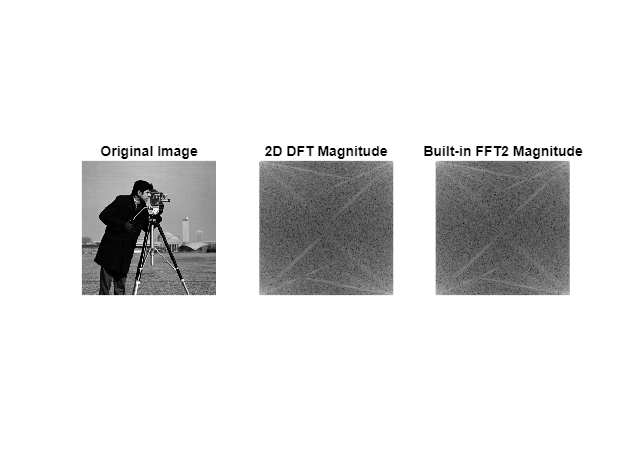

figure;
subplot(1,3,1); imshow(img, []); title('Original Image');
subplot(1,3,2); imshow(log(1+abs(dft_img)), []); title('2D DFT Magnitude');
subplot(1,3,3); imshow(log(1+abs(dft_builtin)), []); title('Built-in FFT2 Magnitude');

**Verify that custom DFT and fft2 give similar results**

error = norm(dft_img - dft_builtin);
disp(['Error between custom DFT and built-in FFT2: ', num2str(error)]);

Error between custom DFT and built-in FFT2: 2.6599e-07


**Proving Five Properties of DFT**

1. Linearity: DFT(a*f1 + b*f2) = a*DFT(f1) + b*DFT(f2)

f1 = randn(size(img)); 
f2 = randn(size(img));
a = 2; b = 3;
lhs = myDFT2_optimized(a*f1 + b*f2);
rhs = a*myDFT2_optimized(f1) + b*myDFT2_optimized(f2);
disp(['Linearity Error: ', num2str(norm(lhs - rhs))]);

Linearity Error: 3.146e-11


2. Shift Property: Shifting in spatial domain results in a phase shift in frequency domain

shifted_img = circshift(img, [10, 10]);
dft_shifted = myDFT2_optimized(shifted_img);
dft_original = myDFT2_optimized(img);
[rows, cols] = size(img);
[x, y] = meshgrid(0:cols-1, 0:rows-1);
phase_shift = exp(-1i * 2 * pi * (10*x/cols + 10*y/rows));
expected_shifted_dft = dft_original .* phase_shift;
disp(['Shift Property Error: ', num2str(norm(dft_shifted - expected_shifted_dft))]);

Shift Property Error: 3.3706e-07


3. Parseval’s Theorem: Energy in spatial and frequency domains should be equal

energy_spatial = sum(img(:).^2);
energy_freq = sum(abs(dft_img(:)).^2) / numel(img);
disp(['Parseval Error: ', num2str(abs(energy_spatial - energy_freq))]);

Parseval Error: 8.1062e-06


4. Conjugate Symmetry Property: For real images, DFT(u,v) = conj(DFT(-u,-v))

conj_symmetric = rot90(conj(dft_img),2);
conj_symmetry_error = norm(dft_img - conj_symmetric) / norm(dft_img);
disp(['Conjugate Symmetry Property Error: ', num2str(conj_symmetry_error)]);

Conjugate Symmetry Property Error: 1.1154


5. Duality Property: The DFT of a DFT (up to scaling and flipping) returns the original image

[M, N] = size(img);
dft_twice = myDFT2_optimized(myDFT2_optimized(img));
img_recovered = rot90(real(dft_twice) / (M * N),2);
duality_error = norm(img - img_recovered) / norm(img);
disp(['Duality Property Error: ', num2str(duality_error)]);

Duality Property Error: 0.052493
